# Lab 5

Ross Smyth

clear, clc, close all
addpath ADSP_ToolBox\

## Project 1

### 2.1: The Shift Property

#### a.

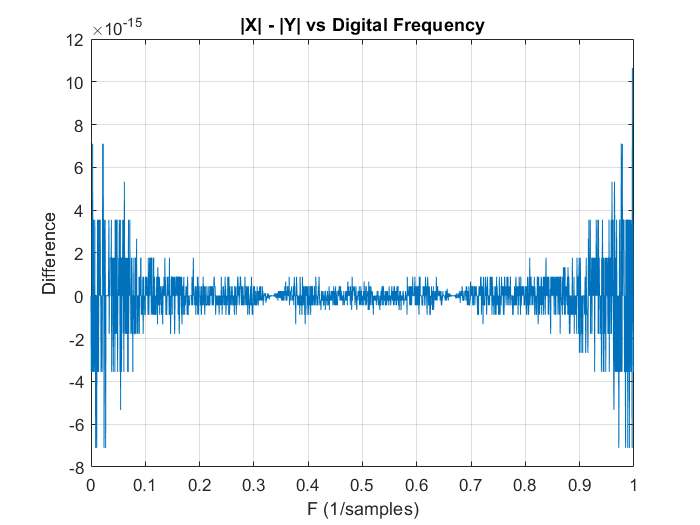

x = [3, 3, 3, 2, 2, 2, 1, 1, 1];
n = -4:4;
F = linspace(0, 1999 / 2000, 2000);
z = exp(2 * pi * 1i * F);

X = polyval(x, z) ./ polyval(udelta(n), z);
Y = polyval(x, z) ./ polyval(udelta(n - 4), z);

XM = abs(X);
XA = angle(X);
XU = unwrap(XA);

YM = abs(Y);
YA = angle(Y);
YU = unwrap(YA);

% Plot
figure()
plot(linspace(0, 1999 / 2000, 2000), XM - YM)
grid
title('|X| - |Y| vs Digital Frequency')
ylabel('Difference')
xlabel('F (1/samples)')

The magnitude of the spectrums should be the same, as the DTFT magnitude is time-shift invariant. This makes sense as the DTFT analyzes the frequency content, which the time of the signal doesn't effect (the magnitude of). There is a small amount of error as seen in the plot above. I would chalk this up to implentation and floating-point errors as they are on the order of ${10}^{-15}$difference. The error is worse near the edges which also makes sense as the boundaries would effect the signal.

#### b.

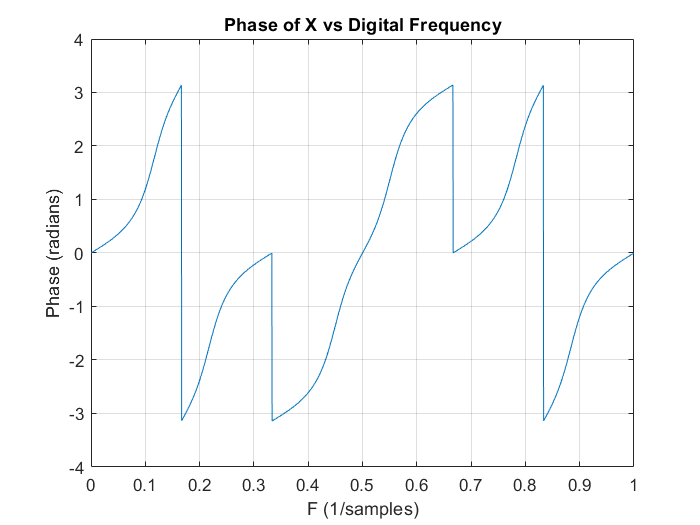

figure()
plot(F, XA)
grid
title('Phase of X vs Digital Frequency')
ylabel('Phase (radians)')
xlabel('F (1/samples)')

The phase is not linear. I would not expect the phase of the data to be linear as there is no reason to expect this set of data to.

#### c.

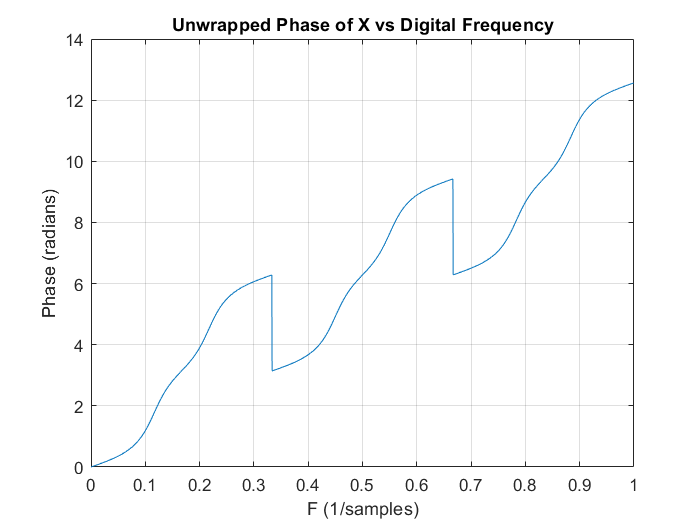

figure()
plot(F, XU)
grid
title('Unwrapped Phase of X vs Digital Frequency')
ylabel('Phase (radians)')
xlabel('F (1/samples)')

The phase X does have discontinuties in the data. This makes sense as the range of the `angle` function is from $\left\lbrack -\pi ,\pi \right\rbrack$, and so it would jump wrap to the lower value of the range after hitting the limit. After running the phase data through the `unwrap` function some of the discontinuities are fixed, but not all of it. Only the discontinuitues from hitting the range limits are removed, but the jumps from 0 to $-\pi$ are not. But because that isn't because of hitting the range limits of the `angle` function, I do not nesscarily believe that those discontinuties are fake, but possibly due to the jumps in the data itself from 3, 2, then 1.

#### d.

all( (XA - YA) < 1E-5) % Because there maybe implmentation/FP errors it uses a tolerance to compare.

ans = logical
   0


The phase data of X doesn't equal the phase data of Y. This is expected because when a signal is time-shifted the magnitude should stay the same, but the phase should not. This is because the phase depends on the value of the signal with time.

#### e.

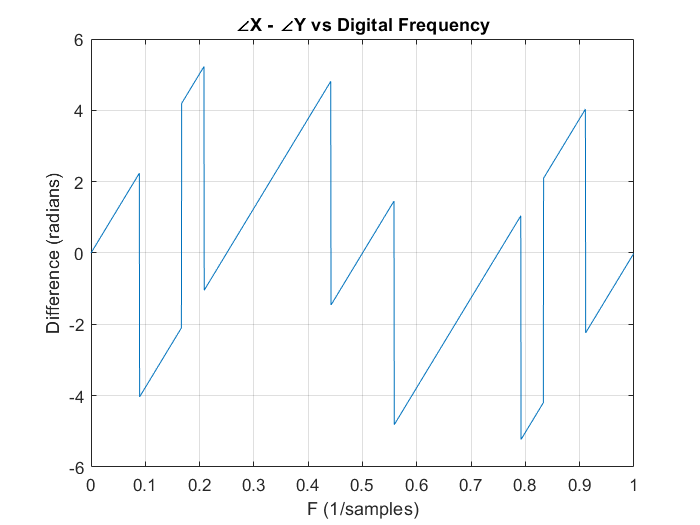

figure()
plot(F, YA - XA)
grid
title('∠X - ∠Y vs Digital Frequency')
ylabel('Difference (radians)')
xlabel('F (1/samples)')

Ignoring the expected discontinuitues in the data, the phase is linear. It should be because when a signal is time shifted, the phase is adjusted by a factor of $e^{-\mathrm{j2}\pi \mathrm{mF}}$ where m is the shift in samples and F is the frequency. This is easily seen to be linear with frequency, so while the phase itself may not be linear, the shift is linear.

#### f.

lin_fit = polyfit(F(1:177), YA(1:177) - XA(1:177), 1);
delay = lin_fit(1) / 2 / pi

delay = 4.0000

There are a couple way to go about finding the delay in samples. If the data is very uniform, then it would be possble to take a single differnce in the samples (Phase X - Phase Y) at a single digital frequnecy value and find the delay. This would be done by the following:


$$\mathrm{delay}=\frac{\angle Y\left(F_n \right)-\angle X\left(F_n \right)}{2\pi F_n }$$


But if the data is jittery, which is a much better assumption, finding the slope of the phases differences is a much safer approach as it will account for many values rather than one. I did this above by doing a linear regression up until the first discontiunity, then dividing the slope by $2\pi$, and correctly found the delay of 4 samples.

### 2.2: Periodicity, Convoluion, Multiplication

#### a.

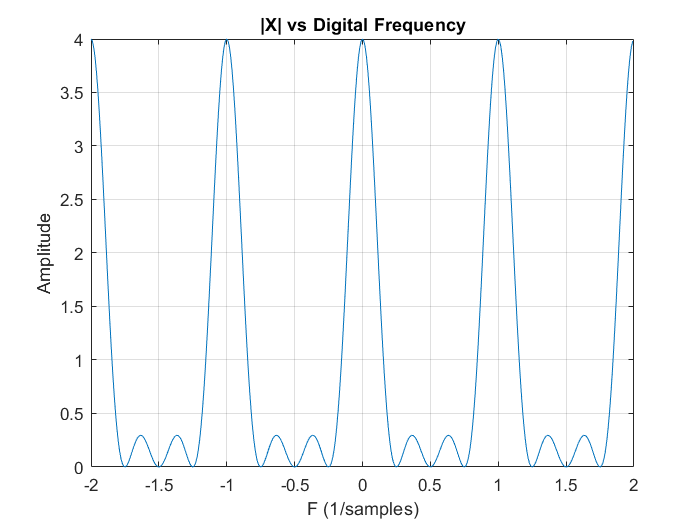

n = 0:8;
x = tri((n - 4) / 4);
F = -2:0.01:1.99;
z = exp(2 * pi * 1i * F);

X = polyval(x, z) ./ polyval(udelta(n), z);
G = polyval(conv(x,x), z) ./ polyval(udelta(0:16), z);
H = polyval(x .* x, z) ./ polyval(udelta(n), z);
Yp = convp(X, X);

figure()
plot(F, abs(X))
grid
title('|X| vs Digital Frequency')
ylabel('Amplitude')
xlabel('F (1/samples)')

It is periodic, and it should be because the DTFT is always periodic, even if sometime the frequency is truncated to only show one period. The period of the DTFT in this case is 1, which is also expected.

#### d.

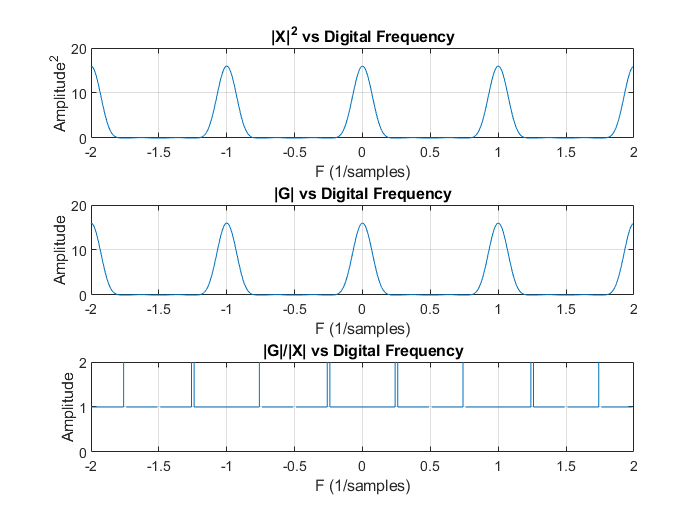

figure()
subplot(3, 1, 1)
plot(F, abs(X).^2)
grid
title('|X|^2 vs Digital Frequency')
ylabel('Amplitude^2')
xlabel('F (1/samples)')

subplot(3, 1, 2)
plot(F, abs(G))
grid
title('|G| vs Digital Frequency')
ylabel('Amplitude')
xlabel('F (1/samples)')

subplot(3, 1, 3)
plot(F, abs(G) ./ (abs(X).^2))
grid
axis([-2, 2, 0, 2])
title('|G|/|X| vs Digital Frequency')
ylabel('Amplitude')
xlabel('F (1/samples)')

These are the same, which is to be expected. The convolution property of the DTFT defines that:


$$G\left(F\right)=X\left(F\right)Y\left(F\right)$$


And since in this case Y=X, G will be $X^2$. The third subplot shows the ratio between $G\left(F\right)\;\mathrm{and}\;X\left(F\right),$ which is mostly 1 (the same), but there are discontinuties due to zero-crossings at some samples.

#### c. 

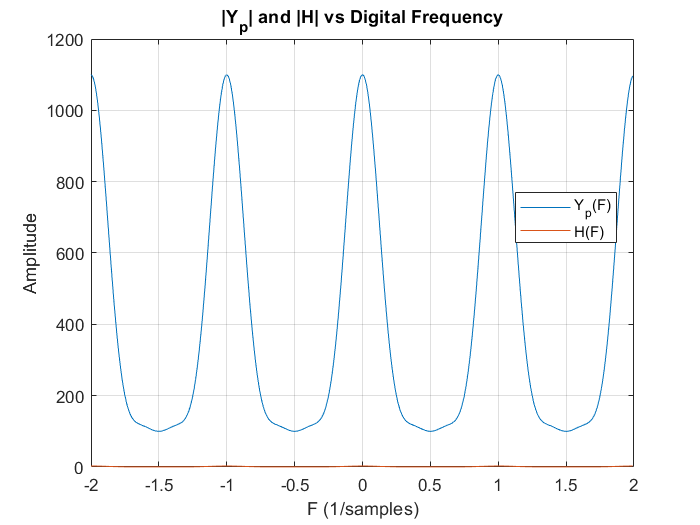

figure()
plot(F, abs(Yp), F, abs(H))
grid
title('|Y_p| and |H| vs Digital Frequency')
legend({'Y_p(F)', 'H(F)'}, 'Location','best')
ylabel('Amplitude')
xlabel('F (1/samples)')

No they are not identical by a significant margin.

#### d.

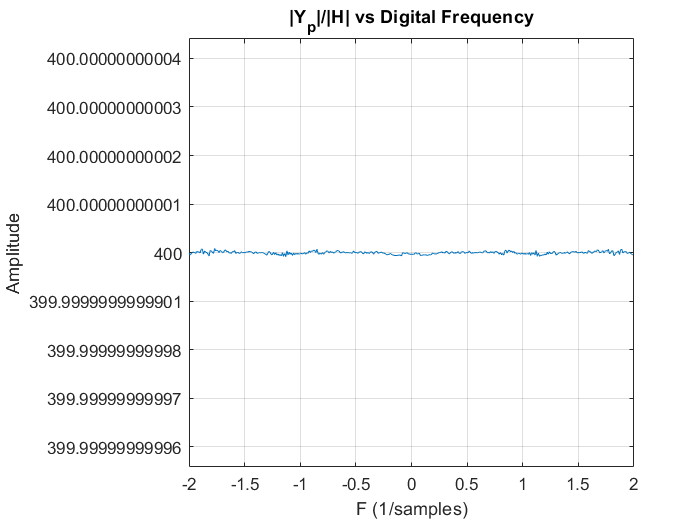

figure()
plot(F, abs(Yp) ./ abs(H))
title('|Y_p|/|H| vs Digital Frequency')
grid
ylabel('Amplitude')
xlabel('F (1/samples)')

The ratio of $\frac{Y_p \left(F\right)}{H\left(F\right)}$ is a constant value of 400. This is also the length of the signal in samples. This means that $H\left(F\right)$ is $Y_P$ normalized by the number of samples.

### 2.3: Modulation

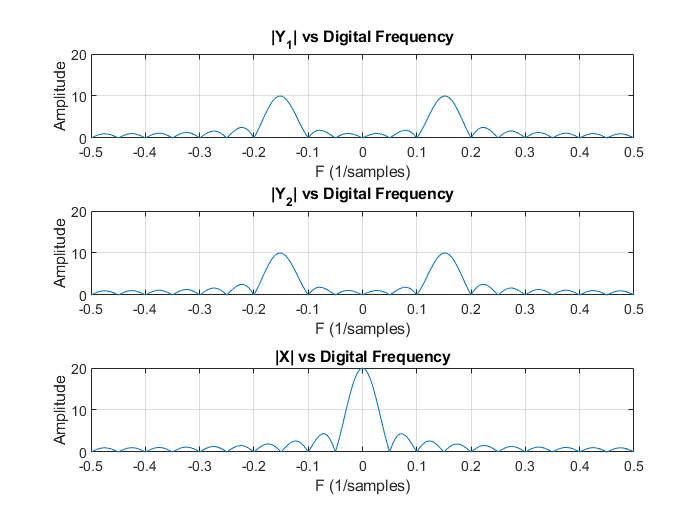

n = 0:19;
x = ones(1, length(n));

y1 = x .* cos(0.3 * pi * n);
y2 = x .* cos(2.3 * pi * n);

F = -0.5:0.005:0.5;
z = exp(2 * pi * 1i * F);

X  = polyval(x, z) ./ polyval(udelta(n), z);
Y1 = polyval(y1, z) ./ polyval(udelta(n), z);
Y2 = polyval(y2, z) ./ polyval(udelta(n), z);

figure()
subplot(3, 1, 1)
plot(F, abs(Y1))
grid
title('|Y_1| vs Digital Frequency')
ylabel('Amplitude')
xlabel('F (1/samples)')
axis([-0.5, 0.5, 0, 20])

subplot(3, 1, 2)
plot(F, abs(Y2))
grid
title('|Y_2| vs Digital Frequency')
ylabel('Amplitude')
xlabel('F (1/samples)')
axis([-0.5, 0.5, 0, 20])

subplot(3, 1, 3)
plot(F, abs(X))
grid
title('|X| vs Digital Frequency')
ylabel('Amplitude')
xlabel('F (1/samples)')
axis([-0.5, 0.5, 0, 20])

#### a.

For $Y_1 \left(F\right)$ the DTFT spectrum should be related by the modulation property of the DTFT, specifically in this case:


$$\mathrm{cos}\left(2\pi n\;0\ldotp 15\right)x\left\lbrack n\right\rbrack \Rightarrow 0\ldotp 5\left\lbrack X\left(F+0\ldotp 15\right)+X\left(F-0\ldotp 15\right)\right\rbrack$$


The first subplot shown above shows this property verified, as it is shifted by 0.15.

#### b.

For $Y_2 \left(F\right)$ the DTFT spectrum should be related by the modulation property of the DTFT, specifically in this case:


$$\mathrm{cos}\left(2\pi n\;1\ldotp 15\right)x\left\lbrack n\right\rbrack \Rightarrow 0\ldotp 5\left\lbrack X\left(F+1\ldotp 15\right)+X\left(F-1\ldotp 15\right)\right\rbrack$$


The first subplot shown above shows this property verified, but only implicitly. Because the DTFT is inherently periodic, the signal shift by 1.15 will be the same as shifting the signal 0.15. Because of this $Y_1 \left(F\right)$ and $Y_2 \left(F\right)$ are identical.

## Project 2

###     1.

####         a.

            Band-stop

####         b.

            IIR

####         c.

            Non-linear

###     2.

####         a.

            Notch

####         b.

            IIR

####         c.

            Non-linear

### 3.

####         a.

            High-pass

####         b.

            FIR

####         c.

            Linear

### 4.

####         a.

            Notch

####         b.

            IIR

####         c.

            Non-linear

### 5.

####         a.

            Band-stop

####         b.

            IIR

####         c.

            Non-linear

### 6.

####         a.

            Band-pass

####         b.

            IIR

####         c.

            Non-linear

### 7.

####         a.

            All-pass

####         b.

            IIR

####         c.

            Non-linear

### 8.

####         a.

            Comb

####         b.

            FIR

####         c.

            Linear